# Value and Consumption Low vs Higher Unemployment Insurance Comparison

This is the example vignette for function: [**snw_vfi_main_bisec_vec**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/svalpol/snw_vfi_main_bisec_vec.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for the V(states, unemployed) assuming individuals suffer from unemployment spell, but with different UI (unemployment benefits). Higher UI benefits leads to value/welfare and also higher consumption.  

## Solve the Steady-State non-unemployment Problem

Solve for Value/Policy in non-COVID years, then solve for covid year value/policy given covid shocks. COVID lasts one period.

% mp_params = snw_mp_param('default_dense');
mp_params = snw_mp_param('default_docdense');
mp_params('beta') = 0.95;
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = false;
mp_controls('bl_timer') = true;
[V_ss,~,cons_ss,~] = snw_vfi_main_bisec_vec(mp_params, mp_controls);

Completed SNW_VFI_MAIN_BISEC_VEC;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=491.2252
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_outcomes ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                i    idx    ndim     numel      rowN      colN           sum         mean       std      coefvari      min          max    
                _    ___    ____    ________    ____    _________    ___________    _______    ______    ________    ________    __________

    V_VFI       

## Solve Problem in MIT Unemployed State with High and Low Unemployment Insurance

Shared xi value, 50 percent income loss. This is a one-time MIT shock that changes choices today in the sense of changing the resource state-space, but does not change forward expectations.

xi=0.5; % xi=0 full income loss from covid shock, xi=1, no covid income losses

Solve for $b=0$, no unemployment insurane.

fl_b_lower = 0.0;
fl_b_higher= 0.5;
b=fl_b_lower; % b=0 means no UI benefits compensating COVID, b=1 if full income replacement
mp_params('xi') = xi;
mp_params('b') = b;
mp_params('a2_covidyr') = mp_params('a2_covidyr_manna_heaven');
% mp_params('a2_covidyr') = mp_params('a2_covidyr_tax_fully_pay');
[V_unemp_b_0p0,~,cons_unemp_b_0p0,~] = snw_vfi_main_bisec_vec(mp_params, mp_controls, V_ss);

Completed SNW_VFI_MAIN_BISEC_VEC 1 Period Unemp Shock;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=485.5335
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_outcomes ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                i    idx    ndim     numel      rowN      colN           sum         mean       std      coefvari      min          max    
                _    ___    ____    ________    ____    _________    ___________    _______    ______    ________    ________    __________

    

Solve for $b=0.5$, 50 percent unemployment insurance, meaning 50 percent of lost income is recovered.

b=fl_b_higher; % b=0 means no UI benefits compensating COVID, b=1 if full income replacement
mp_params('xi') = xi;
mp_params('b') = b;
mp_params('a2_covidyr') = mp_params('a2_covidyr_manna_heaven');
% mp_params('a2_covidyr') = mp_params('a2_covidyr_tax_fully_pay');
[V_unemp_b_0p5,~,cons_unemp_b_0p5,~] = snw_vfi_main_bisec_vec(mp_params, mp_controls, V_ss);

Completed SNW_VFI_MAIN_BISEC_VEC 1 Period Unemp Shock;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=488.1425
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_outcomes ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                i    idx    ndim     numel      rowN      colN           sum         mean       std      coefvari      min          max    
                _    ___    ____    ________    ____    _________    ___________    _______    ______    ________    ________    __________

    

## Generate UI Comparison Matrixes

Find the deviation in value and consumption between higher and lower UI world. Welfare is converted to units in fixed life-time consumption.

gamma = mp_params('gamma');
mn_V_U_gain_moreUI = snw_hh_welfare(V_unemp_b_0p5, gamma) - snw_hh_welfare(V_unemp_b_0p0, gamma);
mn_C_U_gain_moreUI = cons_unemp_b_0p5 - cons_unemp_b_0p0;

## Dense Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids: 
age_grid = 18:100;
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Difference in V and C with Higher and Lower UI

The difference between V and C with higher and ower UI.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('it_legend_select') = 21; % how many shock legends to show
mp_support_graph('cl_colors') = 'jet';

MEAN(MN_V_GAIN(A,Z))

Tabulate value and policies along savings and shocks:

% Set
ar_permute = [1,4,5,6,3,2];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN(A,Z)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_moreUI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN(A,Z)), b\_lower=0, b\_higher=0.5  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21    mean_eta_22    mean_eta_23    mean_eta_24    mean_eta_25    mean_eta_26    mean_eta_27    

% Consumption
st_title = ['MEAN(MN_C_U_GAIN(A,Z)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
tb_az_c = ff_summ_nd_array(st_title, mn_C_U_gain_moreUI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_C_U_GAIN(A,Z)), b\_lower=0, b\_higher=0.5  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21    mean_eta_22    mean_eta_23    mean_eta_24    mean_eta_25    mean_eta_26    mean_eta_27    

Graph Mean Values:

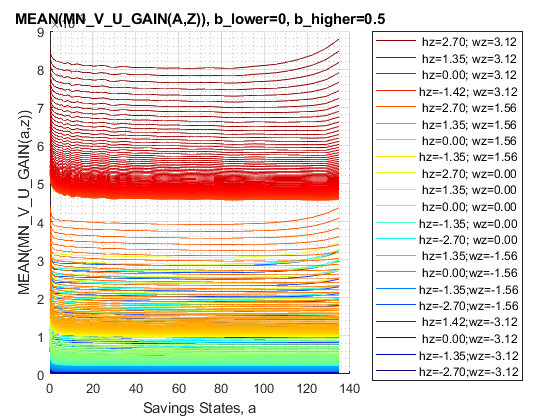

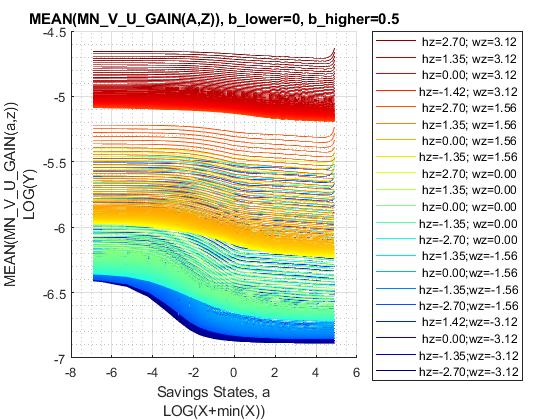

st_title = ['MEAN(MN\_V\_U\_GAIN(A,Z)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption:

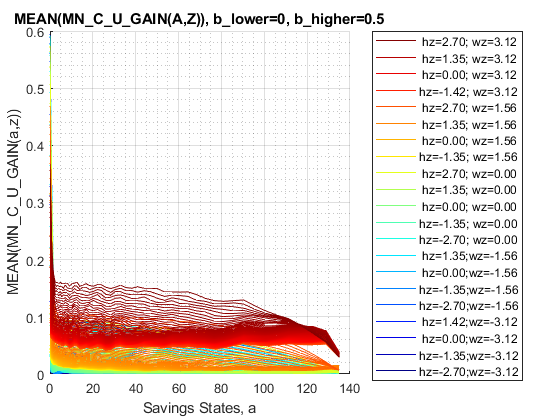

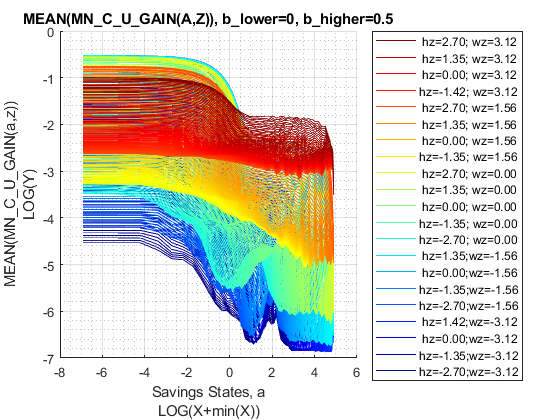

st_title = ['MEAN(MN\_C\_U\_GAIN(A,Z)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_C\_U\_GAIN(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};

MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN(KM,J)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_moreUI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN(KM,J)), b\_lower=0, b\_higher=0.5  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43    <s

% Consumption Function
st_title = ['MEAN(MN_C_U_GAIN(KM,J)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
tb_az_c = ff_summ_nd_array(st_title, mn_C_U_gain_moreUI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_C_U_GAIN(KM,J)), b\_lower=0, b\_higher=0.5  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43    <s

Graph Mean Values:

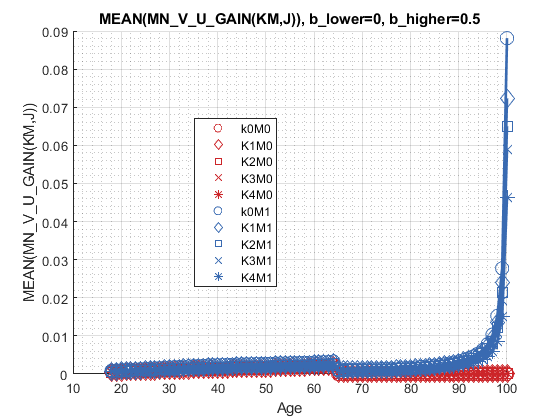

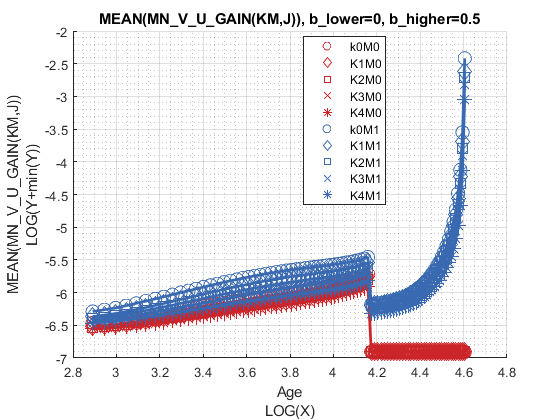

st_title = ['MEAN(MN\_V\_U\_GAIN(KM,J)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

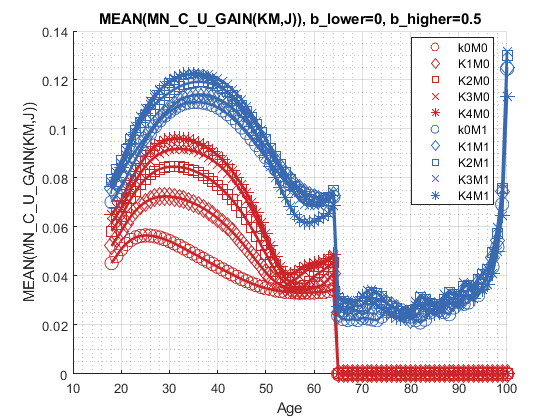

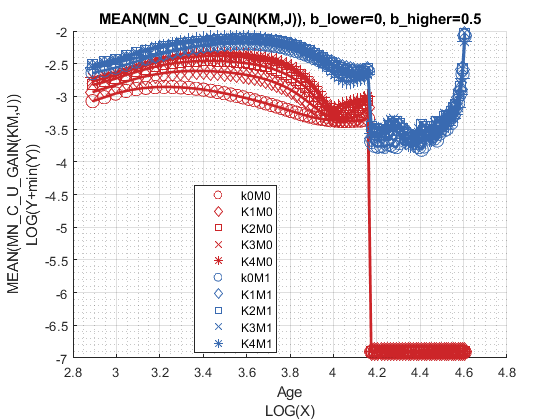

st_title = ['MEAN(MN\_C\_U\_GAIN(KM,J)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_C\_U\_GAIN(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

MEAN(VAL(EM,J)), MEAN(AP(EM,J)), MEAN(C(EM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN(EM,J)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_moreUI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN(EM,J)), b\_lower=0, b\_higher=0.5  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43    

% Consumption
st_title = ['MEAN(MN_C_U_GAIN(EM,J)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
tb_az_c = ff_summ_nd_array(st_title, mn_C_U_gain_moreUI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_C_U_GAIN(EM,J)), b\_lower=0, b\_higher=0.5  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43    

Graph Mean Values:

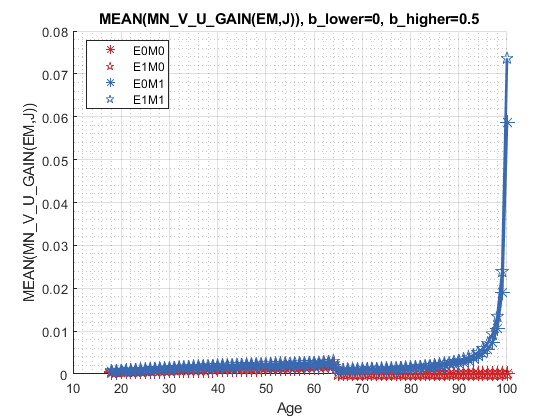

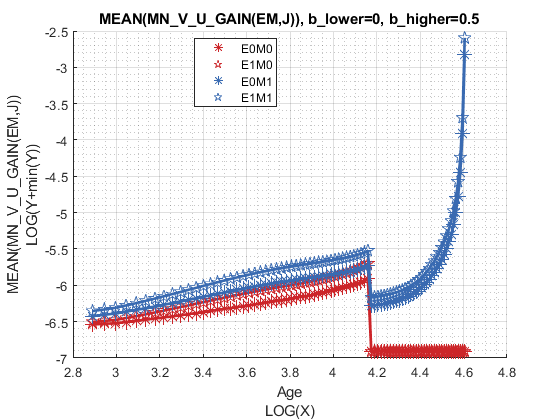

st_title = ['MEAN(MN\_V\_U\_GAIN(EM,J)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

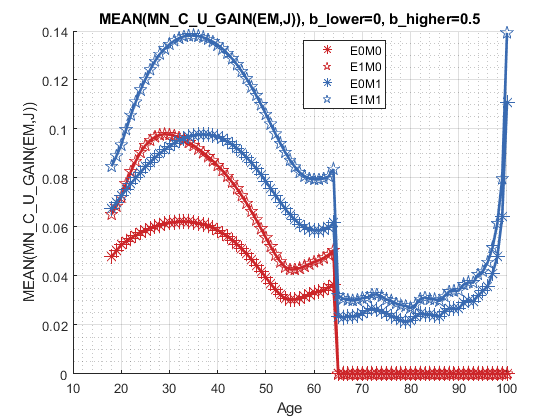

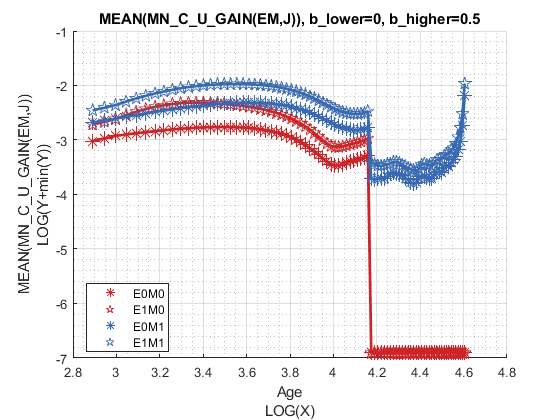

st_title = ['MEAN(MN\_C\_U\_GAIN(EM,J)), b\_lower=' num2str(fl_b_lower) ', b\_higher=' num2str(fl_b_higher)];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_C\_U\_GAIN(EM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);